# `统计学习方法 第二章 测试`

# `Perceptron`

(广东工业大学 自动化学院 控制科学与工程 学一 黄国盛 2112004086  2020.11.28）

%{
本质：（最后的NatureTest 体现了感知机的几何直观）
    构建一个 “模型” 使其能够对 “特征空间的二类标记过程” 进行逼近。
    用“感知机”，不断调整w和b，使其能对所有数据进行正确的二分类
    其核心是定义评价标准（损失函数）并使其最小化
    w和b调整过程（损失函数最小化过程）的核心就是梯度下降法
利用的知识NNI理解：
    这里只评估失误数据的损失程度（相当于正确评估手动筛除）
注：原二类标记是线性的(数据集线性可分)；感知机因为是线性模型，不能表示复杂的函数。
%} 
clear all;  clc;  close all;

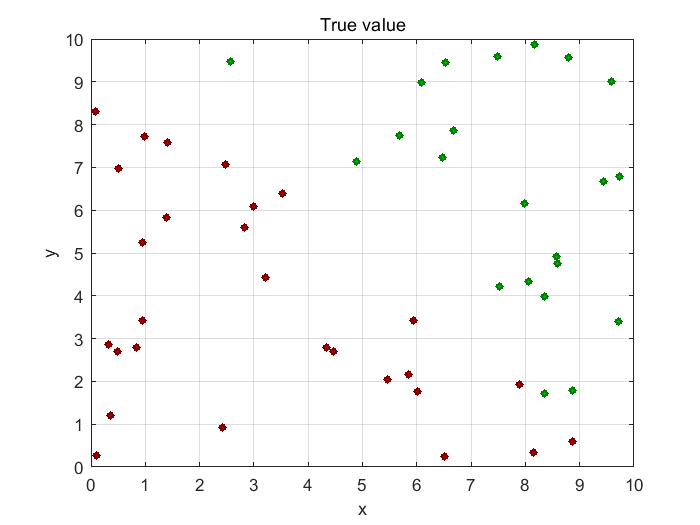

AllPointN = 50;
SquaScalar = 10;
AllRandData = 10*rand(AllPointN,2); % SquaScalar*SquaScalar 内的二维均分布点集
AllRandData(:,3) = sign(10-AllRandData(:,1)-AllRandData(:,2)); % 用对角线划分为两类，标记打在第三列

% AllRandData(:,3)= [1 1 1 0 0 0 -1 -1 -1 0]';
AllRandData(:,3) = PreventZero(AllRandData(:,3),AllPointN); % 避免低概率的 "0"出现

%  采用"提取-分别绘图"的方法, 观察生成的数据
Data1 = AllRandData(AllRandData(:,3)==1, :);  % 行判断，列取值
Data2 = AllRandData(AllRandData(:,3)==-1, :); % 行判断，列取值
figure;  hold on;
grid on;   box on; % 加网格和边框
scatter(Data1(:,1), Data1(:,2), 10, 'MarkerEdgeColor', [0.5 0 0], 'MarkerFaceColor',[0.7 0 0], 'LineWidth',1.5);
scatter(Data2(:,1), Data2(:,2), 10, 'MarkerEdgeColor', [0 0.5 0], 'MarkerFaceColor',[0 0.7 0], 'LineWidth',1.5);
xlabel('x'); ylabel('y');title('True value');


% OrigX = [2 3; 2 4; 2 6; 4 3; 4 5; 4 6; 5 4; 5 5; 6.5 4; 7 3; 4.5 7; 5 8; 6 6; 6 7; 6 9; 7 6; 7 7; 7 8; 8 4; 8 6;]; % 
% ClassY = [1 1 1 1 1 1 1 1 1 1 -1 -1 -1 -1 -1 -1 -1 -1 -1  -1]'; % 20个训练数据 分 正/负类

OrigX = AllRandData(:,1:2); % 
ClassY = AllRandData(:,3);

% length(OrigX)
% length(RealY)
; % ForDebug

% length check
    if ~isequal(length(OrigX),length(ClassY)) 
        error(message('MATLAB: OrigX ClassY Length Mismatch'))
    end
; % ForDebug

Eta = 0.1;   % init learning rate(0 1]
w = [1 1];   % init weight
b = 5;       % init bias

IterCount = 0;
E_Count = 1; % realize do-while struct

while( E_Count ~= 0 )
    
    % Reset
    E_Count = 0;
    ErrorX  = [];
    RecordY = [];
    ; % ForDebug
    
    for i=1:length(ClassY)        
        if( perceptron_calc(w, b, OrigX(i,:)) ~= ClassY(i) )
            E_Count = E_Count+1;
            ErrorX(E_Count,:)   = OrigX(i,:);
            RecordY(E_Count)= ClassY(i);
        end
        ; % ForDebug
    end
    
    [none, RecordY_Column] = size(RecordY);
    ; % ForDebug
    
    if(RecordY_Column>0) % 只取最后一个误分类数据 ？？？ 改为第一个呢 好很多啊？
        w = w + Eta * RecordY(1) * ErrorX(1,:);
        b = b + Eta * RecordY(1);
    end
    ; % ForDebug
    
    disp([IterCount, w, b, E_Count])
    IterCount = IterCount + 1;
end

                   0   0.391178550955640   0.100843565743636   4.900000000000000  22.000000000000000
   1.000000000000000  -0.217642898088720  -0.798312868512729   4.800000000000001  22.000000000000000
   2.000000000000000  -1.103878009414472  -0.976106960335008   4.700000000000001  11.000000000000000
   3.000000000000000  -1.008431485864871  -0.452000950717645   4.800000000000001  21.000000000000000
   4.000000000000000  -0.761490120807375   0.254106643790970   4.900000000000000  16.000000000000000
   5.000000000000000  -1.370311569851735  -0.645049790465395   4.800000000000001  15.000000000000000
   6.000000000000000  -1.123370204794238   0.061057804043220   4.900000000000000  20.000000000000000
   7.000000000000000  -0.308449933346199   0.095891624610949   5.000000000000000   9.000000000000000
   8.000000000000000  -0.917271382390560  -0.803264809645416   4.900000000000000  22.000000000000000
   9.000000000000000  -0.821824858840959  -0.279158800028053   5.000000000000000  21.000000

IterCount

IterCount =    481

w

w =   -1.467833647681991  -1.125492691485706


b

b =   13.999999999999968

% Test
Test_Iter =0;
for i=1:length(ClassY)             
    if( perceptron_calc(w, b, OrigX(i,:)) == ClassY(i) )
        Test_Iter = Test_Iter + 1;
    end
end
Test_Iter % 全样本测试 正确的个数

Test_Iter =     50

% Nature Test: 对b w 做相同同比例变换，Perceptron不受影响
Test_Iter =0;
for i=1:length(ClassY)             
    if( perceptron_calc(2*w, 2*b, OrigX(i,:)) == ClassY(i) )
        Test_Iter = Test_Iter + 1;
    end
end
Test_Iter % 全样本测试 正确的个数

Test_Iter =     50

function [y_hat] = perceptron_calc(w, b, x)

    if(w*x'+b>=0)
        y_hat=1;
    else
        y_hat=-1;
    end

end

function [data] = PreventZero(data,n)
    for i=1:n
        if data(i)==0
            data(i)=1;
        end
    end
end